# Configure Subcomponent Data for AUTOSAR Calibration and Measurement

For any model in an AUTOSAR model reference hierarchy, you can configure the model data for run-time calibration and measurement. In submodels referenced from AUTOSAR software component models, you can map parameters, data stores, signals, and states to AUTOSAR parameters and variables. Submodel mapped internal data can be used in AUTOSAR memory sections, and is available for software-in-the-loop (SIL) and processor-in-the-loop (PIL) testing from the top model or calibration in the AUTOSAR run-time environment.

In this example, AUTOSAR component model `autosar_component` contains two instances of `autosar_subcomponent`.

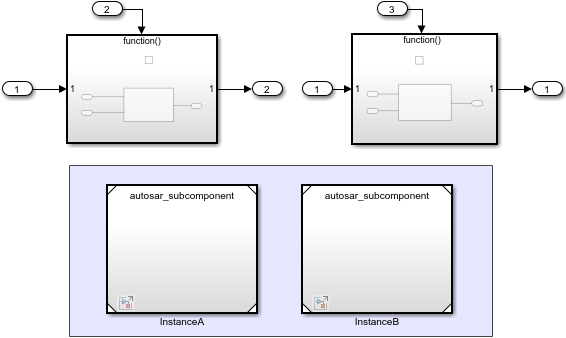

Each instance of `autosar_subcomponent` receives a separate set of parameter values, which you can view in the **Instance parameters** tab of the Model block parameters dialog box.

To configure subcomponent data for run-time calibration and measurement, open the submodel standalone, that is, in a separate model window. Use the Code Mappings editor to:

- Map submodel parameters to AUTOSAR component `PerInstanceParameter`s.

- Map submodel signals, states, and data stores to AUTOSAR `ArTypedPerInstanceMemory` variables.

- Set AUTOSAR code and calibration attributes for the submodel internal data.

To generate C code and AUTOSAR XML (ARXML) files that support run-time calibration of the submodel internal data, open and build the component model that references the submodel.

## Map Submodel Parameters to AUTOSAR Component `PerInstanceParameter`s

Open the example model `autosar_subcomponent`.

open_system('autosar_subcomponent');

At the top level is a Simulink Function, for which the top model provides per-instance parameters. Open the Simulink Function.

From the **Apps** tab, open the AUTOSAR Component Designer app. Open the Code Mappings editor and select the **Parameters** tab. The example submodel has four model workspace parameters, including a lookup table parameter. To map each Simulink parameter to an AUTOSAR per-instance parameter, select each parameter and, in the **Mapped To** drop-down list, select `PerInstanceParameter`.

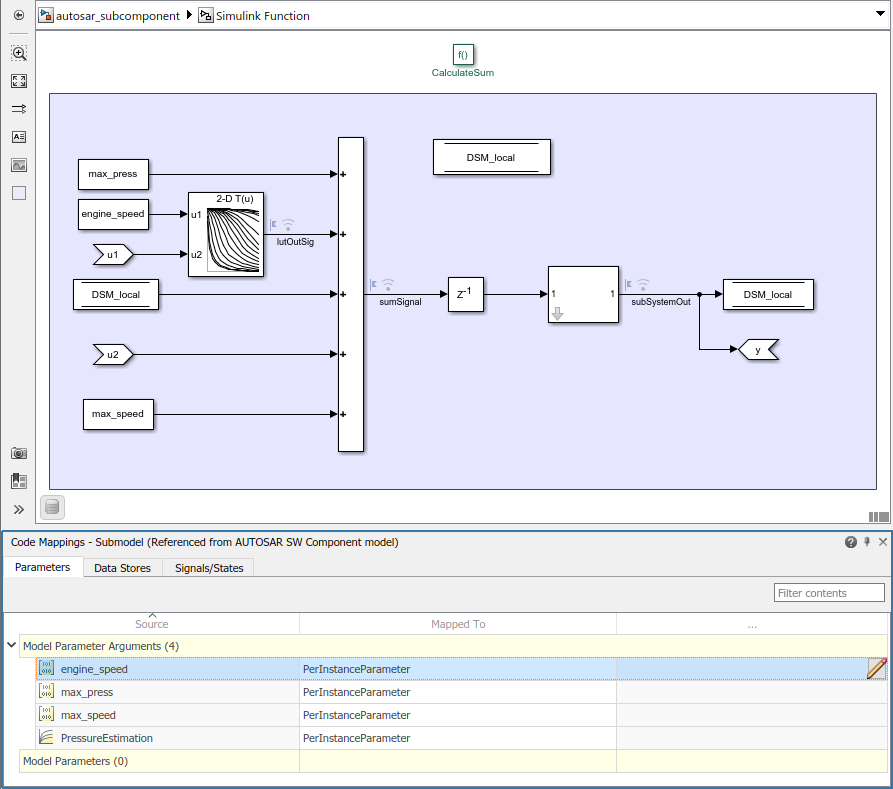

Select the parameter `engine_speed`. To view and modify additional AUTOSAR attributes for the per-instance parameter, click the   icon. A properties dialog box opens.

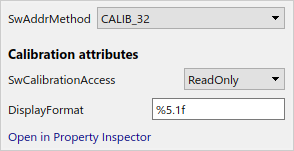

For each AUTOSAR `PerInstanceParameter`, you can modify the `SwAddrMethod` (AUTOSAR memory section), the calibration data access, and the calibration data display format. For more information about parameter code and calibration attributes, see [Map Submodel Parameters to AUTOSAR Component Parameters](docid:autosar_ug.mw_624259fd-d87d-4f48-990b-f37ef9604f54).

When you generate code from the component model that references the submodel:

- Exported ARXML files contain PER-INSTANCE-PARAMETERS descriptions for submodel parameters that you configured as AUTOSAR component `PerInstanceParameter`s, and descriptions of the `SwAddrMethod`s referenced in the submodel.

- Generated C code references the submodel AUTOSAR per-instance parameters.

- The model build generates macros that provide access to the submodel data for SIL and PIL testing and calibration in the AUTOSAR run-time environment.

## Map Submodel Data Stores to AUTOSAR `ArTypedPerInstanceMemory` Variables

If they are not already open, open the example model `autosar_subcomponent`, the top-level Simulink Function, the AUTOSAR Component Designer app, and the Code Mappings editor.

In the Code Mappings editor, select the **Data Stores** tab. The example submodel has a Data Store Memory block named `DSM_local`. To map the Simulink data store to an AUTOSAR-typed per-instance memory variable, select `DSM_local`. Selecting a data store highlights the Data Store Memory block in the model diagram. In the **Mapped To** drop-down list, select `ArTypedPerInstanceMemory`.

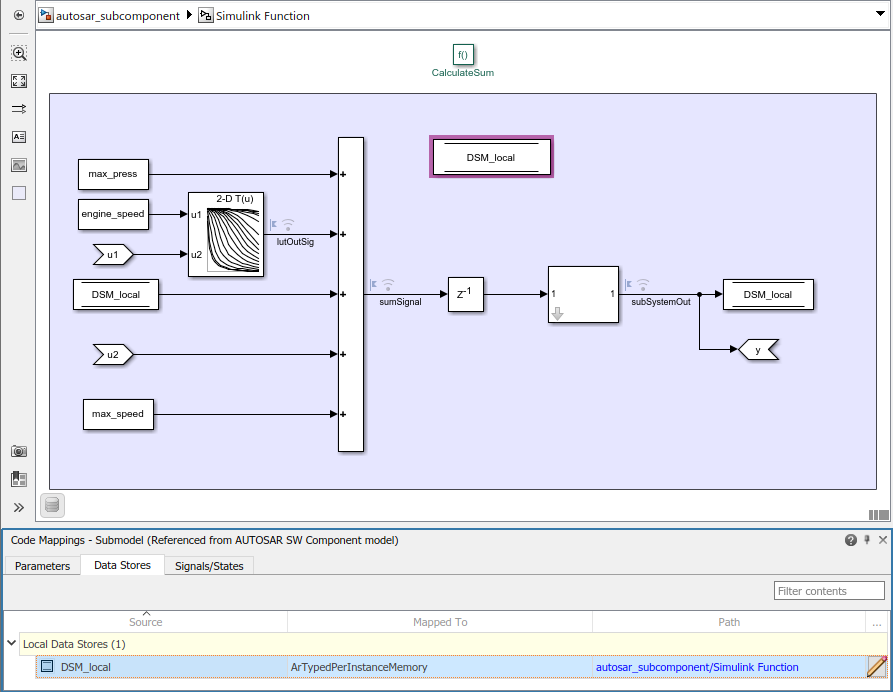

To view and modify additional AUTOSAR attributes for the per-instance memory, click the   icon. A properties dialog box opens.

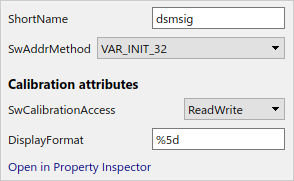

For each AUTOSAR `ArTypedPerInstanceMemory` variable, you can modify the ARXML short name, the `SwAddrMethod` (AUTOSAR memory section), the calibration data access, and the calibration data display format. For more information about data store code and calibration attributes, see [Map Submodel Data Stores to AUTOSAR Variables](docid:autosar_ug.mw_c8839b0d-e1a8-4073-900f-70738179082f).

When you generate code from the component model that references the submodel:

- Exported ARXML files contain AR-TYPED-PER-INSTANCE-MEMORYS descriptions for submodel data stores that you configured as `ArTypedPerInstanceMemory` variables, and descriptions of the `SwAddrMethods` referenced in the submodel.

- Generated C code references the submodel AUTOSAR-typed per-instance memory variables.

- The model build generates macros that provide access to the submodel data for SIL and PIL testing and calibration in the AUTOSAR run-time environment.

## Map Submodel Signals and States to AUTOSAR `ArTypedPerInstanceMemory` Variables

If they are not already open, open the example model `autosar_subcomponent`, the top-level Simulink Function, the AUTOSAR Component Designer app, and the Code Mappings editor.

In the Code Mappings editor, select the **Signals/States** tab. The **Signals/States** tab lists each Simulink block signal and state that you can map to an AUTOSAR variable. The example submodel has three mappable signals and one state. To map each Simulink signal and state to an an AUTOSAR-typed per-instance memory variable, select each signal or state. Selecting a signal or state highlights the element in the model diagram. In the **Mapped To** drop-down list, select `ArTypedPerInstanceMemory`.

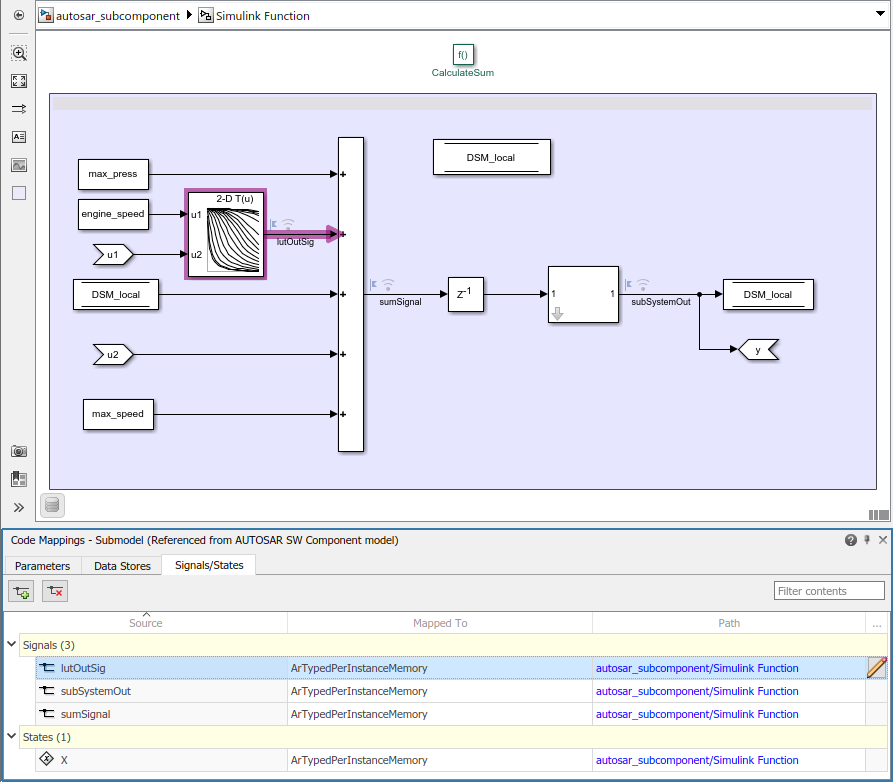

To make additional Simulink block signals available for mapping, use a Code Mappings editor button or a model cue:

- In the model canvas, select one or more signals. Open the Code Mappings editor, **Signals/States** tab, and click the **Add** button.

- In the model canvas, select a signal. Place your cursor over the displayed ellipsis and select model cue **Add selected signals to code mappings**.

In the Code Mappings editor, select the signal `lutOutSig`. To view and modify additional AUTOSAR attributes for the per-instance memory, click the   icon. A properties dialog box opens.

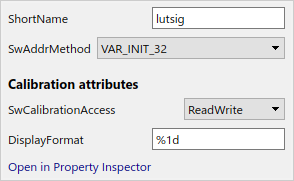

For each AUTOSAR `ArTypedPerInstanceMemory` variable, you can modify the ARXML short name, the `SwAddrMethod` (AUTOSAR memory section), the calibration data access, and the calibration data display format. For more information about signal and state code and calibration attributes, see [Map Submodel Signals and States to AUTOSAR Variables](docid:autosar_ug.mw_8ec2e22d-a9cf-4411-8a18-925b72428775).

When you generate code from the component model that references the submodel:

- Exported ARXML files contain AR-TYPED-PER-INSTANCE-MEMORYS descriptions for submodel signals and states that you configured as `ArTypedPerInstanceMemory`, and descriptions of the `SwAddrMethod`s referenced in the submodel.

- Generated C code references the submodel AUTOSAR-typed per-instance memory variables.

- The model build generates macros that provide access to the submodel data for SIL and PIL testing and calibration in the AUTOSAR run-time environment.

## Related Links

- [Map Calibration Data for Submodels Referenced from AUTOSAR Component Models](docid:autosar_ug.mw_fddb39db-436a-406b-8ab6-2a7bb34ea308)

- [Generate Submodel Data Macros for Verification and Deployment](docid:autosar_ug.mw_23a69932-f839-46a8-9fac-5baf1ee9174e)

- [Configure Model Workspace Parameters as AUTOSAR Per-Instance Parameters](docid:autosar_ug.mw_3919e400-02d0-4bab-afef-4d0bca5bdec7)

- [Configure AUTOSAR Per-Instance Memory](docid:autosar_ug.bsn97zd)

- [Code Mappings Editor](docid:autosar_ref.mw_ar0788eb-fc60-4606-9ffe-a2730autosar)

*Copyright 2021 The MathWorks, Inc.*